## SECTION 1: Choose a directory path on your computer for class assignments

In a MATLAB script, anything that comes after the percent sign (%) is displayed in green, and it is interpreted as a COMMENT (not as an executable code statement). All other text (not in green) is executable code. 

Read through the code comments below. If necessary, make changes to the code as instructed.

% ----- SECTION 1 CODE BLOCK

% this command clears all variables from the MATLAB workspace: 
clear all; % it is a good idea for any MATLAB program to start with this command

% After clearing the workspace, the first thing we will do is create a new
% file directory on your computer for your Psych 119D class files. 

% On Windows machines, there is a permanent MATLAB variable called 'userpath' 
% that contains the name of a parent folder where user programs should be stored. 
% If the 'userpath' variable exists, then we can set the userpath folder as the
% parent folder for our Psych 119D directory:

if exist('userpath')
    parentfolder=userpath;

% On MacOS machines, 'userpath' often does not exist. If the 'userpath' variable 
% does not exist, then we can set the parent folder for our Psych 119D directory 
% to be MATLAB's Present Working Directory (pwd): 

else
    parentfolder=pwd;
end

% Now that we have set the parent directory, we can display the location
% where the Psych 119D folder will be created (this statement will only
% display the suggested file path to the Psych 119D directory; it will NOT yet
% create the directory on your computer):

classfolder = 'C:\Users\ericy\OneDrive\Desktop\UCLA College stuffs\Senior Class\Winter\PSYCH 119D\MATLAB';

If you click anywhere inside of the code block above, you can then run the code by clicking the 'Run Section' button in the menu bar. Make sure that you click 'Run Section' and not 'Run'!

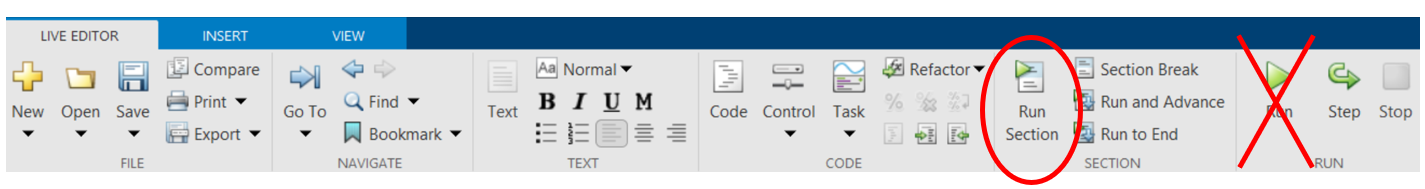

After you run the code, you will see the 'classfolder' directory path that MATLAB suggests to create for storing your Psych 119D files. THIS WILL BE THE DIRECTORY THAT YOU USE FOR THE REST OF THE QUARTER TO STORE YOUR CLASS FILES!!!!!!! 

If you are OK with MATLAB's suggestion, then proceed to Section 2. Alternatively, if prefer to use a directory different from the one MATLAB suggests, then you can edit the code on line 30 to set your own directory path; for example:

classfolder = 'C:/MyPath/Psych119D'

After you edit line 30, rerun the code block (by clicking 'Run Section' again) to make sure the directory path you entered is correct. When you are sure it is correct, move on to section 2.    

## SECTION 2: Create the class directory and your student ID file

Now that you have chosen a path for your class directory, we will create the directory and store a student ID (SID) file that contains your student ID number. When you turn in your Psych 119D assignments, MATLAB will read your student ID number from the SID file and automatically attach it to your submissions. 

**IMPORTANT INSTRUCTIONS**: Edit line 37 of the code below as instructed:

% ----- SECTION 2 CODE BLOCK

% this command creates the file directory specified by the code from section 1:
mkdir(classfolder); 


% EDIT THE LINE BELOW!!!!!! Replace 123456789 with your own 9-digit student ID number:
SID = '3104615746';

% the code below will create the SID file in your class folder, and then store your 
% SID number into that file:
filename = [classfolder '/SIDfile.m'];
sidCommand = sprintf(['SID=' SID ';']);
rngCommand = sprintf('rng(SID);');
fid = fopen(filename, 'w'); % open the file for writing
if fid == -1
    error('Cannot open file for writing.'); % quit if there is an error
else
    fprintf(fid, '%s\n', sidCommand);    % Write the ID number to the file
    fprintf(fid, '%s\n', rngCommand);    
    fclose(fid);
end

After entering you SID on line 37 above, click anywhere inside of the code block and then run the code by clicking the 'Run Section' button in the menu bar.

**IMPORTANT NOTE**: If you do any of your future MATLAB assignments on a computer other than the one you are using now, then you will need to copy your SID file to that new computer so that your SID information can be submitted with the file. Please ask the instructor for help if this situation arises. 

## SECTION 3: Create $x_1$ and $x_2$ matrices (2D state space)

In class, we considered the example of a single neuron that mutliplies two integers $x_1$ and $x_2$ to obtain their product. We specified that $x_1$ and $x_2$ were both integers on the interval [-10,10], so input vectors $\mathbf{x}=\left\lbrace x_i ,x_j \right\rbrace$ were sampled from a space of 441 points on a 21x21 grid: 

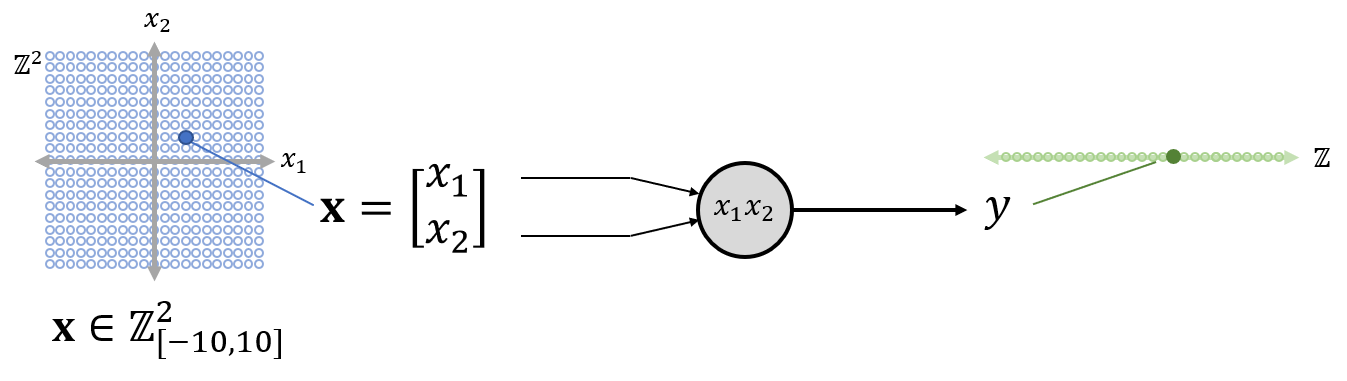

MATLAB has a command called 'meshgrid' that lets us easily create the entire set of 441 possible input vectors.  Run the script below (with 'Run Section') to create two 21x21 matrix variables: one for x1, and another for x2. **THEN ANSWER QUESTION 1 USING THE DROPDOWN BELOW.** 

% create two 21x21 matrices, one for X1 and another for X2
[X1, X2] = meshgrid(-10:10, -10:10); % X1 and X2 are both constrained to the interval -10:10 

X1 % contents of the X1 matrix variable will be displayed below (click on table to inspect values)

X1 =    -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10
   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10
   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10
   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10
   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10
   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10
   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10
   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6    


X2 % contents of the X2 matrix variable will be displayed below (click on table to inspect values)

X2 =    -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9
    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7
    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    

**QUESTION 1:** Which of the two tables above (X1 or X2) contains the same witthin each row and different values within each column? Use the dropdown menu below to select your answer:

answer1 = "X2"

answer1 = "X2"

## SECTION 4: Element-wise matrix multiplication

Now we can easily create a new 21x21 matrix called Y in which each entry is the product of corresponding entries in X1 and X2. That is, $y\left(i,j\right)=x_1 \left(i,j\right)\times \;x_2 \left(i,j\right)$. To create Y, run the script below with 'Run Section':  

% Y is the element-wise product of X1 and X2: 
Y = X1 .* X2 % contents of the Y matrix variable will be displayed below (click on table to inspect values)

Y =    100    90    80    70    60    50    40    30    20    10     0   -10   -20   -30   -40   -50   -60   -70   -80   -90  -100
    90    81    72    63    54    45    36    27    18     9     0    -9   -18   -27   -36   -45   -54   -63   -72   -81   -90
    80    72    64    56    48    40    32    24    16     8     0    -8   -16   -24   -32   -40   -48   -56   -64   -72   -80
    70    63    56    49    42    35    28    21    14     7     0    -7   -14   -21   -28   -35   -42   -49   -56   -63   -70
    60    54    48    42    36    30    24    18    12     6     0    -6   -12   -18   -24   -30   -36   -42   -48   -54   -60
    50    45    40    35    30    25    20    15    10     5     0    -5   -10   -15   -20   -25   -30   -35   -40   -45   -50
    40    36    32    28    24    20    16    12     8     4     0    -4    -8   -12   -16   -20   -24   -28   -32   -36   -40
    30    27    24    21    18    15    12     9     6     3     0    -3    -6    -9   -12   -15   -18   -2

Notice that this code uses the element-wise multiplication operator .* to create Y.  

Why did we write Y = X1 .* X2 instead of Y = X1 * X2? Because we want each entry in Y to be the element-wise product of corresponding entries from X1 and X2. This is called 'element-wise' multiplication, and it is denoted by the .* symbol in MATLAB. 

If we had instead written Y = X1 * X2, then we would have obtained the 'matrix product' of X1 and X2 (not the element-wise product). The matrix product is a concept from linear algebra that we will discuss later in the course. For a brief (optional) tutorial on the difference between matrix multiplication and element-wise multiplication in MATLAB, see the following short video:     

[https://www.youtube.com/watch?v=lcstBp24YFE](https://www.youtube.com/watch?v=lcstBp24YFE)

## SECTION 5: Plot the function $y=x_1 x_2$ as a surface 

In class we learned that whenever a function has a vector input and a scalar output, it is possible to plot the function as a surface in a vector space with N+1 dimensions (where N is the dimensionality of the input vector):

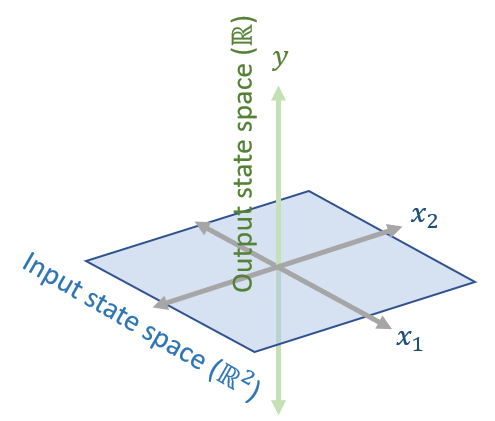

Multiplying two numbers is an example of such a function, since its takes a vector of two numbers $\mathbf{x}=\left\lbrace x_i ,x_j \right\rbrace$ as its input and produces a scalar value $y$ as its output. input So, let's plot Y as a surface over the plane X1,X2 by running the script below:    

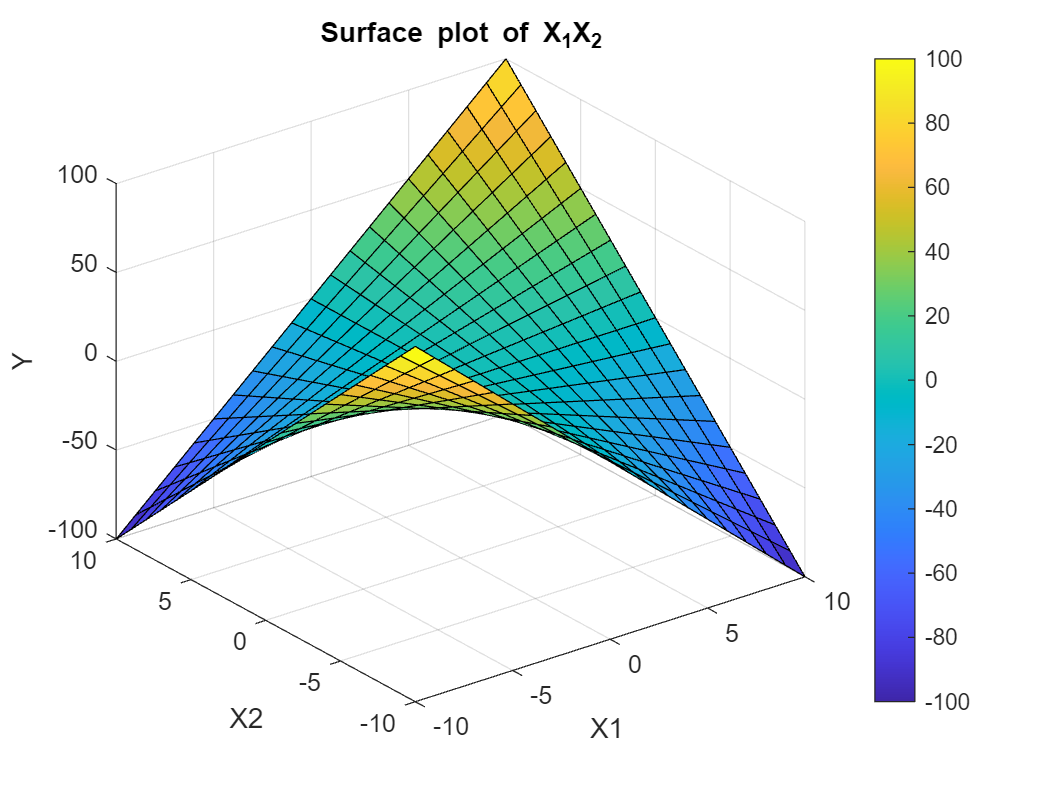

surf(X1, X2, Y); % plot Y as a surface over the plane of X1 and X2

% label the axes
xlabel('X1');
ylabel('X2');
zlabel('Y');

%title the graph
title('Surface plot of X_{1}X_{2}');
colorbar; %draw a color bar

view(3); % Set a nice 3D viewing angle

## SECTION 6: Plot the function $y=x_1 {\;+\;x}_2$ as a surface

Adding two numbers is another example of a function that takes a vector of two numbers $\mathbf{x}=\left\lbrace x_i ,x_j \right\rbrace$ as its input and produces a scalar value $y$ as its output. So, let's store the sum X1+X2 in a matrix called S and then plot S as a surface over the plane X1,X2 by running the script below:    

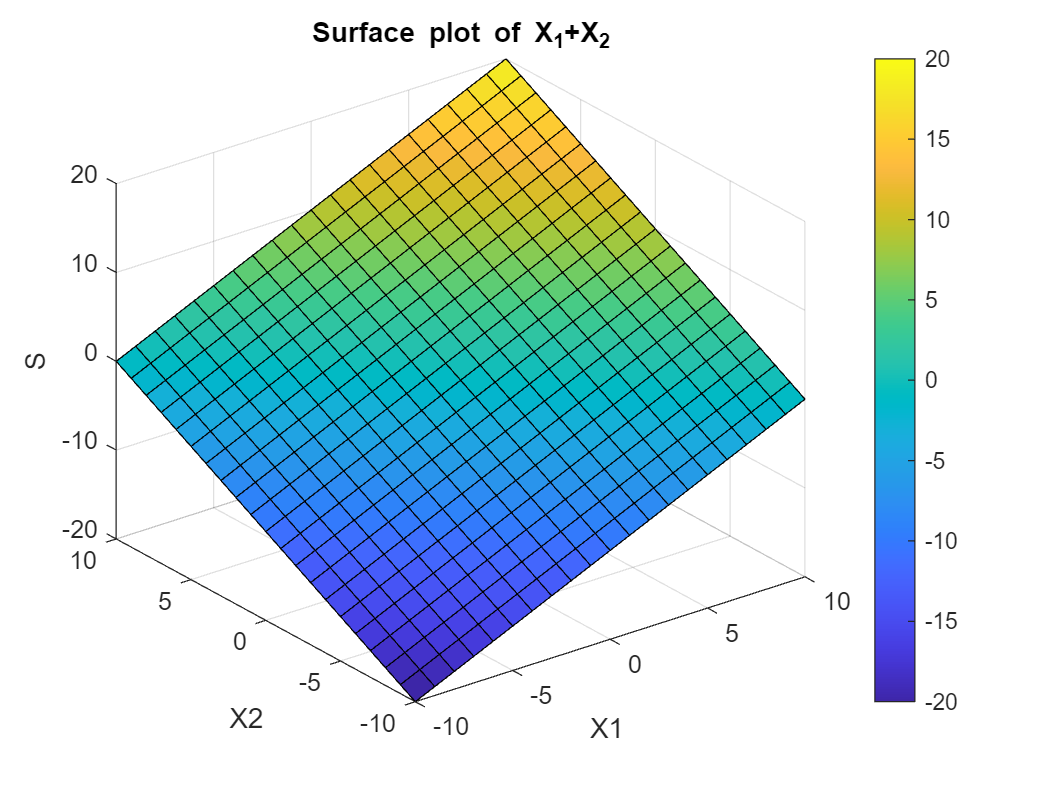

S = X1 + X2;
surf(X1, X2, S); % plot a 3D surface of Y over X1 and X2

% label the axes
xlabel('X1');
ylabel('X2');
zlabel('S');

%title the graph
title('Surface plot of X_{1}+X_{2}');
colorbar; %draw a color bar

view(3); % Set a nice 3D viewing angle

## SECTION 7: Plot the function $y={\left(x_1 \right)}^2 +{\left(x_2 \right)}^2$ as a surface

Another example of a function that takes a vector of two numbers as its input and produces a scalar value $y$ as its output is the paraboloid function: $y=x_i^2 +x_j^2$

So, let's store a paraboloid in a matrix called P and then plot P as a surface over the plane X1,X2 by running the script below:    

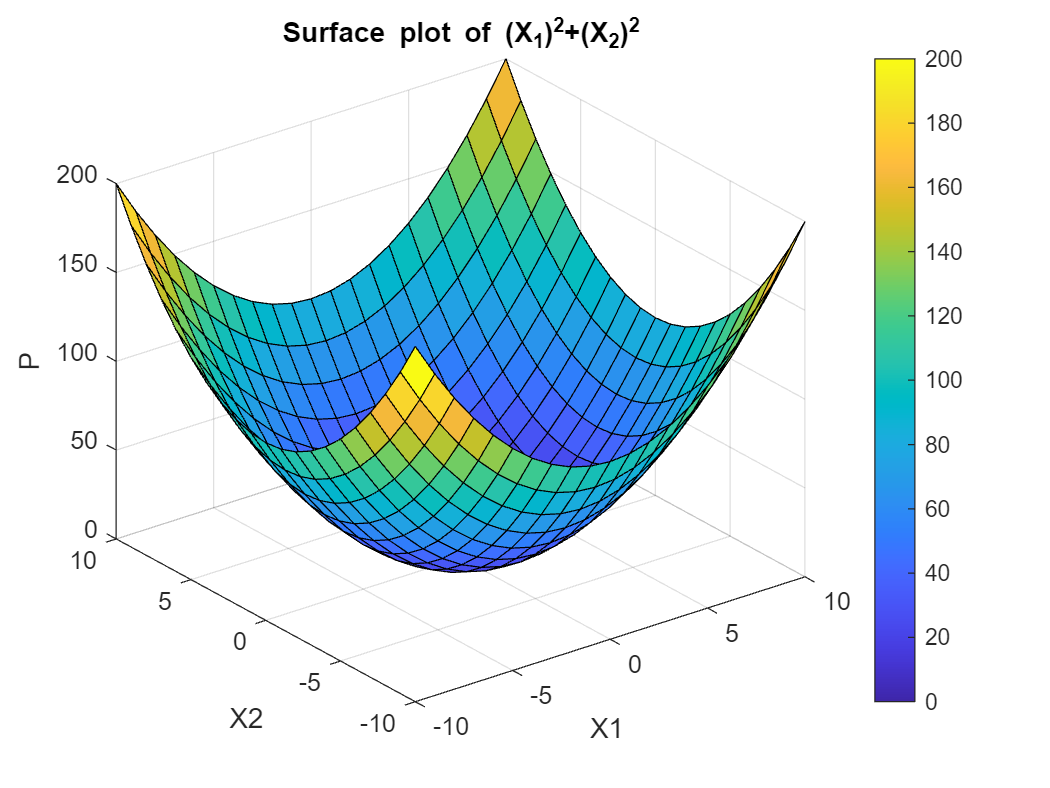

P = X1.^2 + X2.^2;
surf(X1, X2, P); % plot a 3D surface of Y over X1 and X2

% label the axes
xlabel('X1');
ylabel('X2');
zlabel('P');

%title the graph
title('Surface plot of (X_{1})^{2}+(X_{2})^{2}');
colorbar; %draw a color bar

view(3); % Set a nice 3D viewing angle

Here again, notice that to create P, the code uses the element-wise exponential operator .^ to square X1 and X2.  

Why did we write P = X1.^2 + X2.^2 instead of P = X1^2 + X2^2? Because squaring a matrix is the same as multiplying it by itself, and as we saw aboive, we can either use element-wise multiplication or matrix multiplication when we multiply one matrix by another (including itself). Here, we want element-wise multiplication so we write X1.^2 (which is the same as X1.*X1); if we had written X1^2 (which is the same as X1*X1) then we would have been using matrix multiplication.

The paraboloid P is a special type of surface called a CONVEX SURFACE. Mathematically, convexity means that the line segment between any two points on the surface does not fall below the surface itself. More intuitively, convexity means that the surface is shaped like a bowl, and if we dropped a marble onto the surface it would roll to the bottom of the bowl. 

We will more to say about convex surfaces soon!

## SECTION 8: You are done! Submit your work to Canvas

To submit your assignment, follow three steps:

1) run the script below by clicking inside the code window and then hitting 'Run Section' (three graphs will appear below the code)

2) a file called '123456789_assignment1.png' will be created in your 119D directory (with your SID in place of 123456789)

3) upload this file to Canvas to submit your completed assignment!

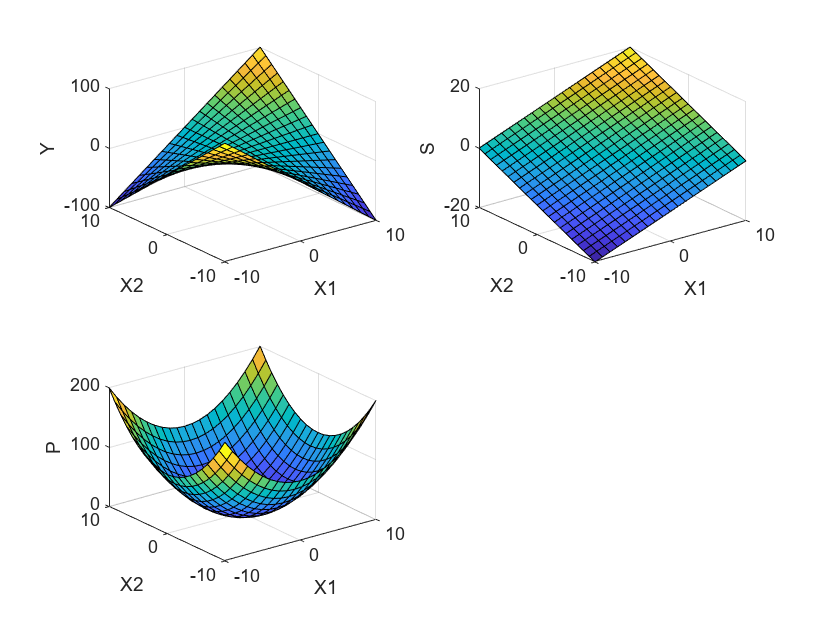

% PLOT FIGURE AND SAVE FILE TO SUBMIT ON CANVAS

figure(1); clf;

subplot(2,2,1);
surf(X1, X2, Y); 
xlabel('X1'); ylabel('X2'); zlabel('Y');
view(3); 

subplot(2,2,2);
surf(X1, X2, S); 
xlabel('X1'); ylabel('X2'); zlabel('S');
view(3); 

subplot(2,2,3);
surf(X1, X2, P); 
xlabel('X1'); ylabel('X2'); zlabel('P');
view(3); 

filename = [num2str(SID) '_assignment1.png'];
figure(1);
saveas(gcf, [classfolder '/' filename]);

[I, map] = imread([classfolder '/' filename]);
metadata = struct('SID', num2str(SID),'ans1',answer1);
imwrite(I, [classfolder '/' filename], 'png', 'SID', metadata.SID, 'ans1', metadata.ans1);
info = imfinfo(filename);